# TAREA 6

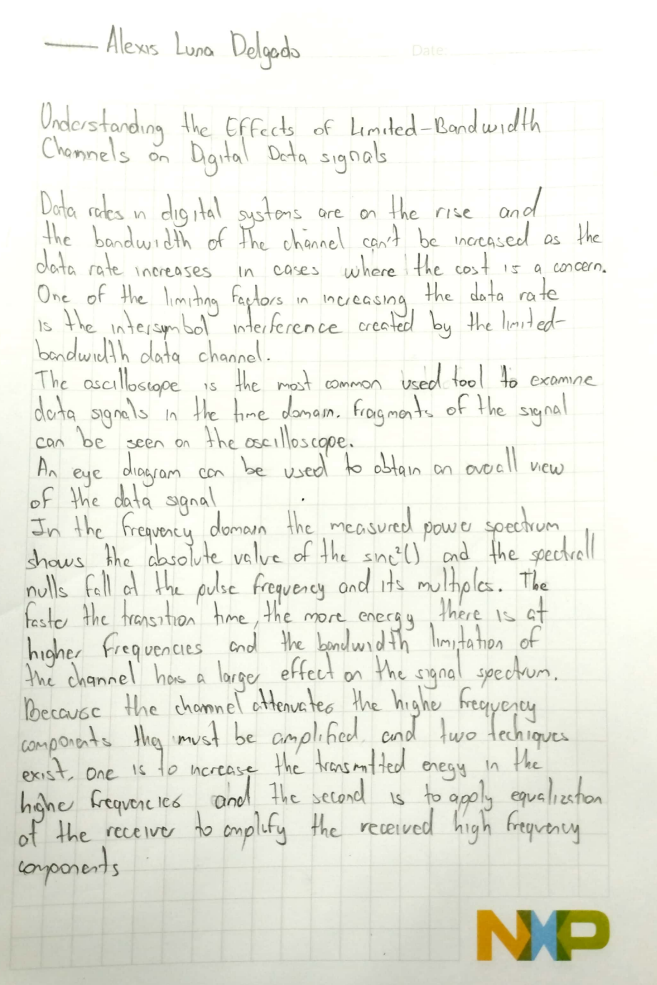

## LENA

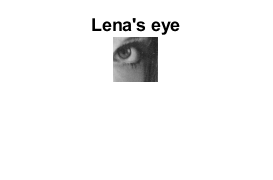

load lena512.mat
lenarec = lena512(252:296,318:362);% Crop the image to a 45 x 45 vector
figure(1);
imshow(uint8(lenarec))
title("Lena's eye");

b = de2bi(lenarec,8,'left-msb'); % Convert the samples from uint8 to binary
b = b';     
bits = b(:);



## EJERCICIO 1

ford=100;     % Orden del Filtro 
f=   [0 0.3045 0.3045 1];  % Vector de Frecuencias
m= [1 1 0 0]; % Vector de Magnitudes 
f1 = fir2(ford,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f2)    
f=   [0 0.1545 0.1545 1];  % Vector de Frecuencias 
f2 = fir2(ford,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f1)          % Herramienta para analizar el Filtro 
f=   [0 0.045 0.045 1];  % Vector de Frecuencias
f3 = fir2(ford,f,m);     % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f2)    


Fs= 96000;
mp= 10;
%No_bits= 8712;
Baud_rate= Fs/mp   %Symbols per second

Baud_rate = 9600

Bit_rate=Baud_rate % bits/s

Bit_rate = 9600

Ts=1/Fs;
% The bit rate is Rb= Rs= Fs / mp, because 1 bit= 1 symbol and  every symbol has mp
% samples per bit

## b.1- Filtre la señal Unipolar NRZ con los tres canales de comunicación.

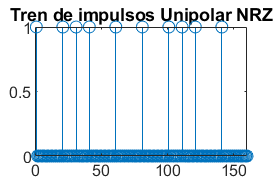


%pnrz = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; % Pulse type with mp samples
pnrz =ones(1,mp); % Similar to Arduino pulses with 5V
%wvtool(pnrz)

s = zeros(1,numel(bits)*mp);
s(1:mp:end) = bits;  % Impulse Train
stem(s(1:mp*16))
title('Tren de impulsos Unipolar NRZ');

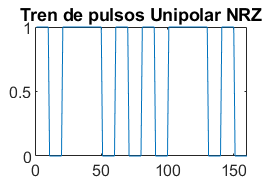

xUNRZ = conv(pnrz,s); % Pulse Train
plot(xUNRZ(1:mp*16))
title('Tren de pulsos Unipolar NRZ');

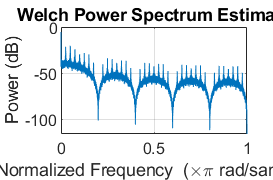

pwelch(xUNRZ,[],[],[],'power'); % PSD of Unipolar NRZ

%%wvtool(xUNRZ)

pow = sum(xUNRZ.^2)/numel(xUNRZ);
pow_Deseada = 1;
xUNRZ = sqrt(pow_Deseada/pow)*xUNRZ;

soundsc(xUNRZ, Fs);

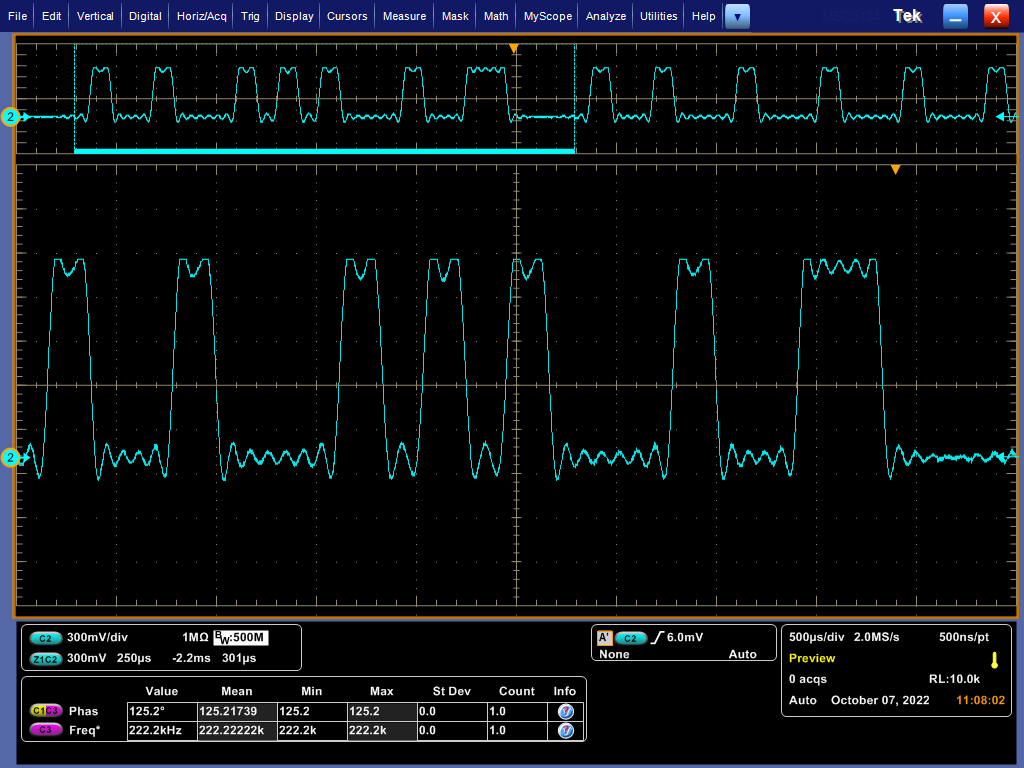

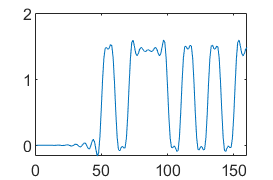

xUNRZ_filtrado_f1 = conv(xUNRZ,f1);
xUNRZ_filtrado_f2 = conv(xUNRZ,f2);
xUNRZ_filtrado_f3 = conv(xUNRZ,f3);

%c)
plot(xUNRZ_filtrado_f1(1:mp*16));

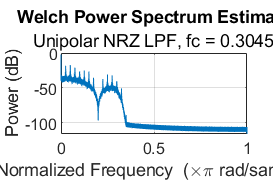

pwelch(xUNRZ_filtrado_f1,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.3045"); 

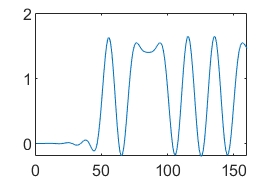

plot(xUNRZ_filtrado_f2(1:mp*16));

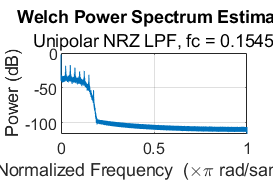

pwelch(xUNRZ_filtrado_f2,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.1545"); 

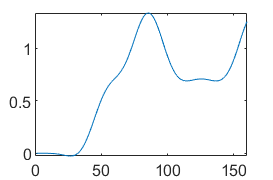

plot(xUNRZ_filtrado_f3(1:mp*16));

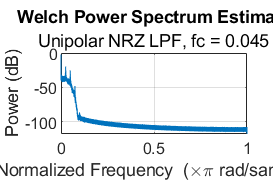

pwelch(xUNRZ_filtrado_f3,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.045"); 

## b.2- Filtre la señal Polar NRZ con los tres canales de comunicación.

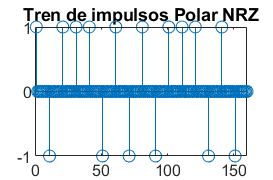


pnrz=ones(1,mp);
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))
title('Tren de impulsos Polar NRZ');

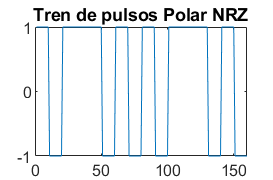

xPNRZ=conv(pnrz,s); %Pulse train
plot(xPNRZ(1:mp*16))
title('Tren de pulsos Polar NRZ');

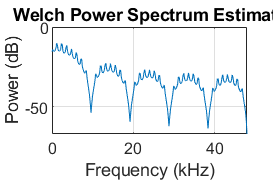

pwelch(xPNRZ,500,300,500,Fs,'power');


pow = sum(xPNRZ.^2)/numel(xPNRZ);
pow_Deseada = 1;
xPNRZ = sqrt(pow_Deseada/pow)*xPNRZ;

soundsc(xPNRZ, Fs);

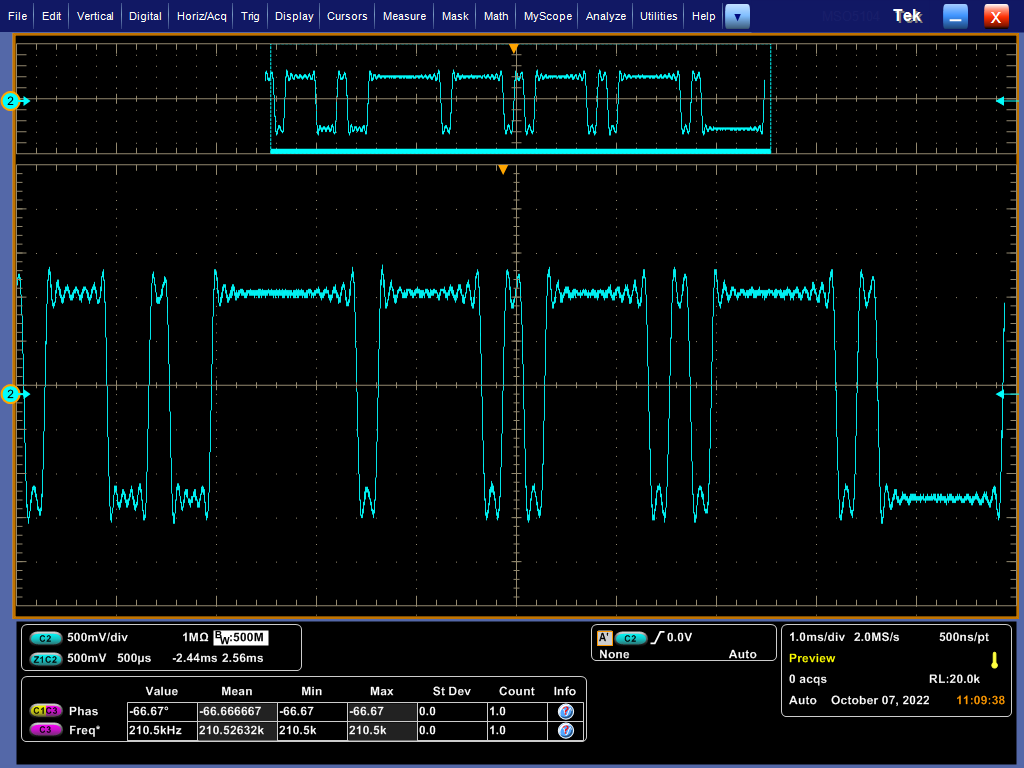

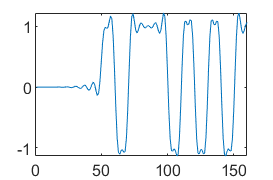

xPNRZ_filtrado_f1 = conv(xPNRZ,f1);
xPNRZ_filtrado_f2 = conv(xPNRZ,f2);
xPNRZ_filtrado_f3 = conv(xPNRZ,f3);

%c)
plot(xPNRZ_filtrado_f1(1:mp*16));

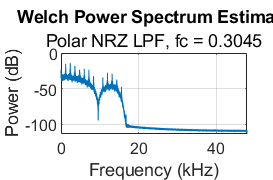

pwelch(xPNRZ_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.3045"); 

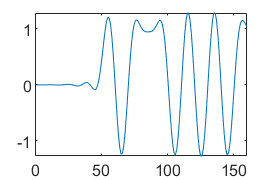

plot(xPNRZ_filtrado_f2(1:mp*16));

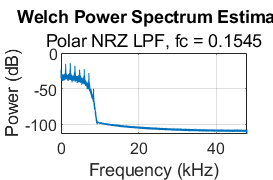

pwelch(xPNRZ_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.1545"); 

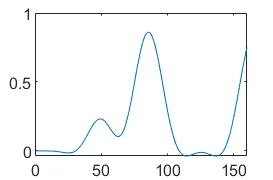

plot(xPNRZ_filtrado_f3(1:mp*16));

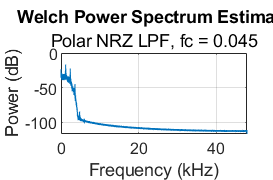

pwelch(xPNRZ_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.045"); 

## b.3- Filtre la señal Manchester con los tres canales de comunicación.

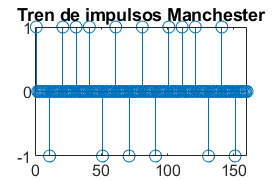



pm=[ones(1,mp/2),-1*ones(1,mp/2)]; 
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(bits)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Manchester');

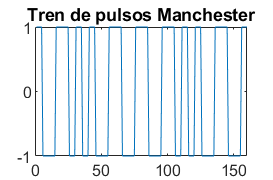

xMANCH=conv(pm,s);
plot(xMANCH(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Manchester');

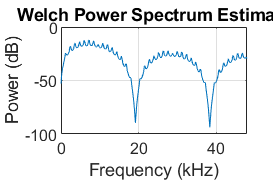

pwelch(xMANCH,500,300,500,Fs,'power');


pow = sum(xMANCH.^2)/numel(xMANCH);
pow_Deseada = 1;
xMANCH = sqrt(pow_Deseada/pow)*xMANCH;

soundsc(xMANCH, Fs);

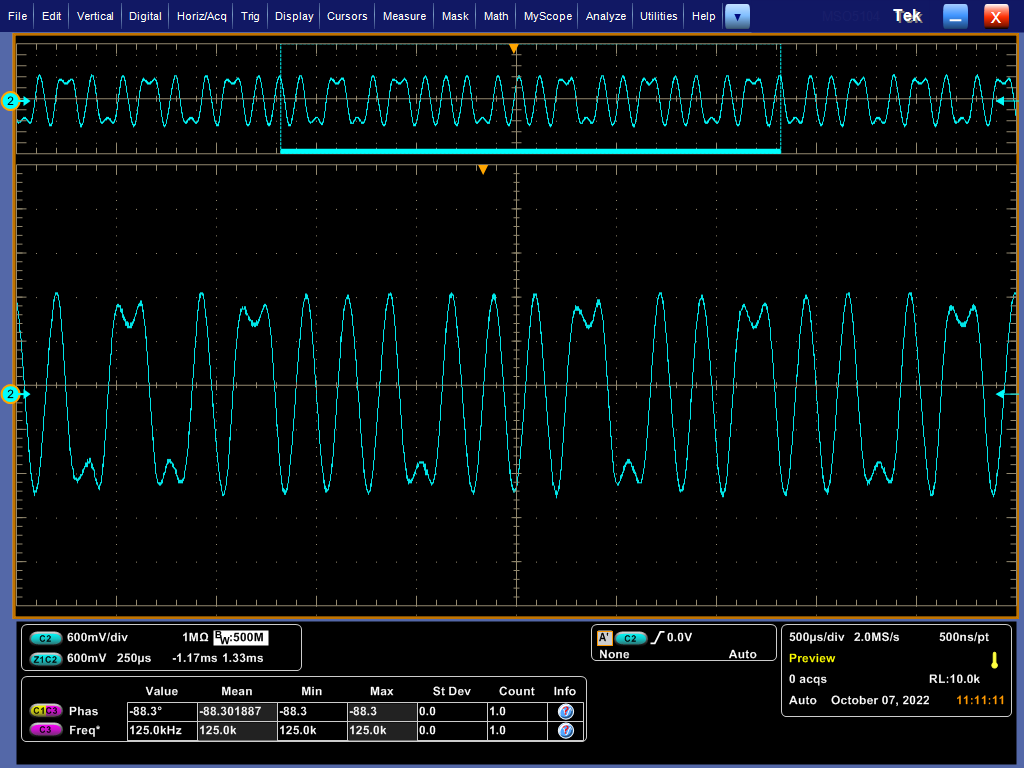

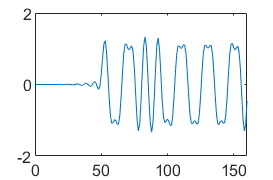

xMANCH_filtrado_f1 = conv(xMANCH,f1);
xMANCH_filtrado_f2 = conv(xMANCH,f2);
xMANCH_filtrado_f3 = conv(xMANCH,f3);

%c)
plot(xMANCH_filtrado_f1(1:mp*16));

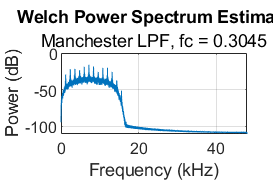

pwelch(xMANCH_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.3045"); 

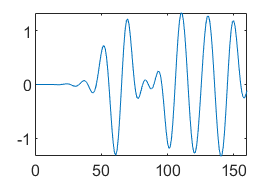

plot(xMANCH_filtrado_f2(1:mp*16));

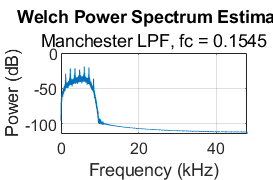

pwelch(xMANCH_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.1545"); 

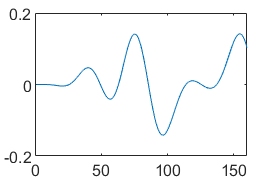

plot(xMANCH_filtrado_f3(1:mp*16));

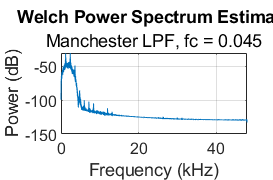

pwelch(xMANCH_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.045"); 

## b.4- Filtre la señal AMI RZ con los tres canales de comunicación.

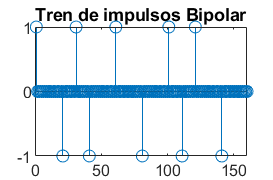


pAMI = [ones(1,mp),zeros(1,mp)];
s1 = bits;
flag = boolean(0);
for k= 1:numel(s1);
    if (s1(k)==1)
        if (flag == 1)
           s1(k)=-1;
        end
        flag = ~flag;
    end
end
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Bipolar');

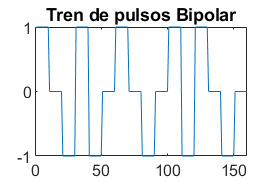

xAMI=conv(pAMI,s);
plot(xAMI(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Bipolar');

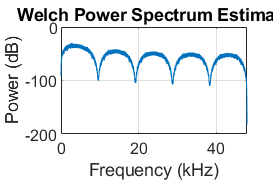

pwelch(xAMI, [],[],[],Fs,'power');


pow = sum(xAMI.^2)/numel(xAMI);
pow_Deseada = 1;
xAMI = sqrt(pow_Deseada/pow)*xAMI;

soundsc(xAMI, Fs);

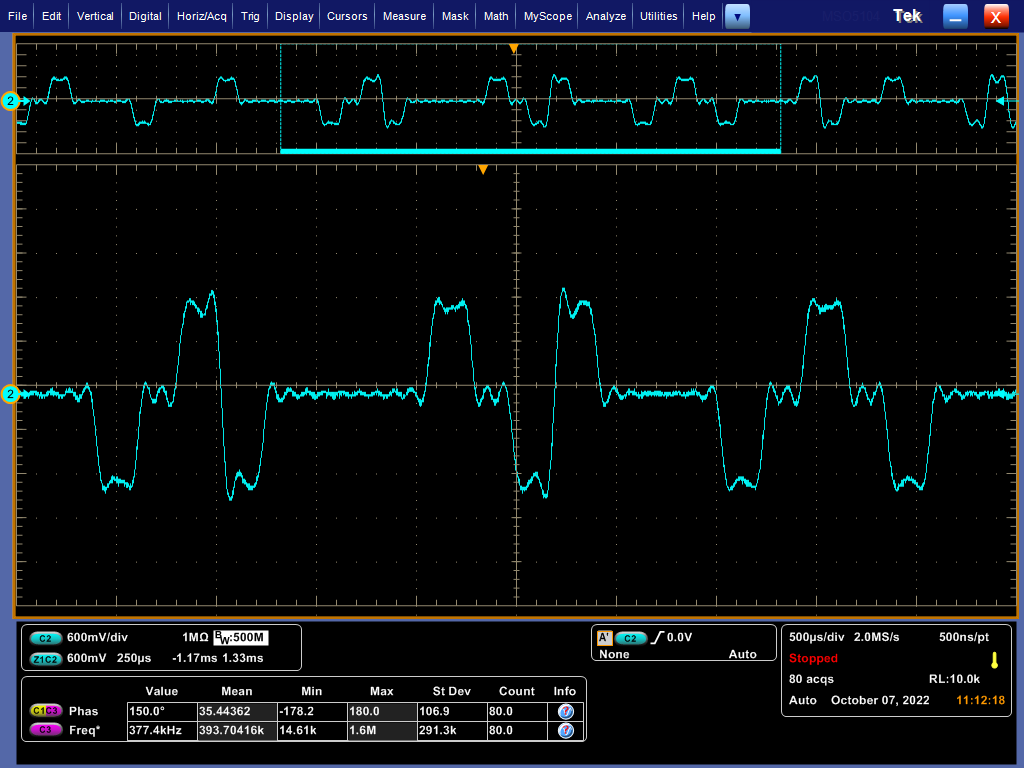

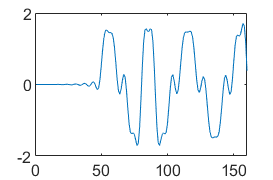


xAMI_filtrado_f1 = conv(xAMI,f1);
xAMI_filtrado_f2 = conv(xAMI,f2);
xAMI_filtrado_f3 = conv(xAMI,f3);

%c)
plot(xAMI_filtrado_f1(1:mp*16));

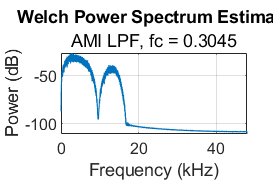

pwelch(xAMI_filtrado_f1,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.3045"); 

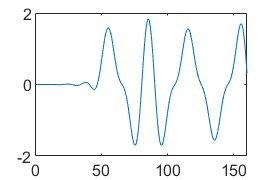

plot(xAMI_filtrado_f2(1:mp*16));

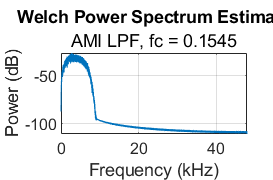

pwelch(xAMI_filtrado_f2,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.1545"); 

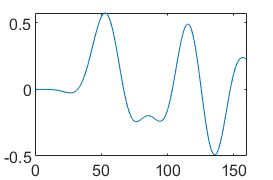

plot(xAMI_filtrado_f3(1:mp*16));

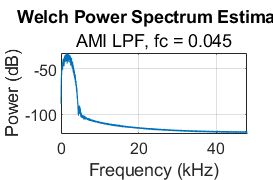

pwelch(xAMI_filtrado_f3,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.045"); 

## b.5- filter PRZ

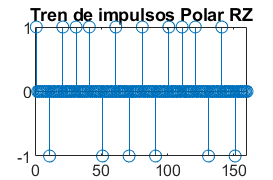

% Polar RZ

%Baud_rate= Fs/mp %Symbols per second
%Bit_rate=Baud_rate % bits/s
pprz=[ones(1,mp/2),zeros(1,mp/2)];
s1=int8(bits);
s1(bits==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Polar RZ');

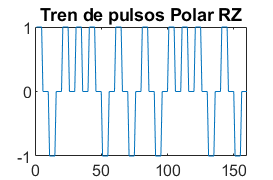

xprz=conv(pprz,s);
plot(xprz(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Polar RZ');

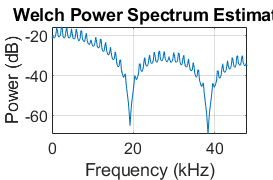

pwelch(xprz,500,300,500,Fs,'power');



pow = sum(xprz.^2)/numel(xprz);
pow_Deseada = 1;
xprz = sqrt(pow_Deseada/pow)*xprz;

soundsc(xprz, Fs);

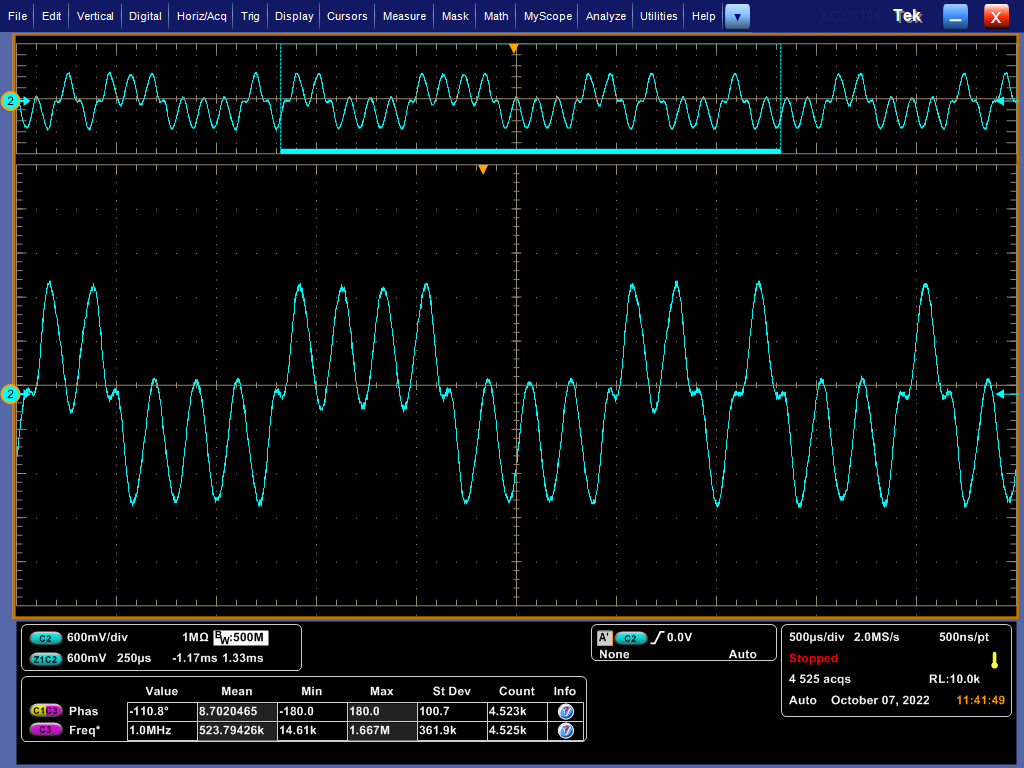

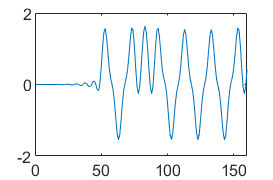

% Filtered Polar RZ
pRZ_lpf_1 = conv(xprz, f1);
pRZ_lpf_2 = conv(xprz, f2);
pRZ_lpf_3 = conv(xprz, f3);


%c)
plot(pRZ_lpf_1(1:mp*16));

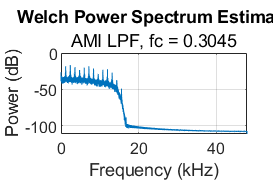

pwelch(pRZ_lpf_1,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.3045"); 

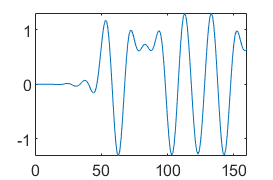

plot(pRZ_lpf_2(1:mp*16));

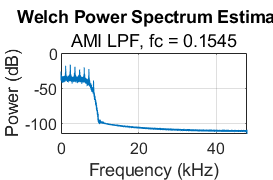

pwelch(pRZ_lpf_2,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.1545"); 

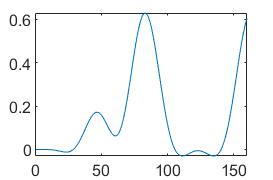

plot(pRZ_lpf_3(1:mp*16));

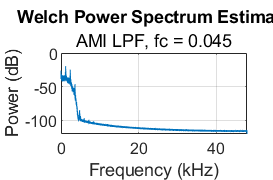

pwelch(pRZ_lpf_3,[],[],[],Fs,'power'); % PSD of Unipolar NRZ
subtitle("AMI LPF, fc = 0.045"); 

% 1.e) recover the transmitted bits
% UNRZ
bits2send = bits';
bits_RX_UNRZ_1 = zeros(1,numel(bits2send));
bits_RX_UNRZ_2 = zeros(1,numel(bits2send));
bits_RX_UNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
xUNRZ_f_m1 = xUNRZ_filtrado_f1(start:mp:end);
xUNRZ_f_m2 = xUNRZ_filtrado_f2(start:mp:end);
xUNRZ_f_m3 = xUNRZ_filtrado_f3(start:mp:end);

bits_RX_UNRZ_1(xUNRZ_f_m1 > (max(xUNRZ_filtrado_f1)/2)) = 1;   %Umbral +
bits_RX_UNRZ_2(xUNRZ_f_m2 > (max(xUNRZ_filtrado_f2)/2)) = 1;   %Umbral +
bits_RX_UNRZ_3(xUNRZ_f_m3 > (max(xUNRZ_filtrado_f3)/2)) = 1;   %Umbral +

xUNRZ_BER_1 = (sum(xor(bits2send,bits_RX_UNRZ_1))/numel(bits2send)) * 100

xUNRZ_BER_1 = 0

xUNRZ_BER_2 = (sum(xor(bits2send,bits_RX_UNRZ_2))/numel(bits2send)) * 100

xUNRZ_BER_2 = 0

xUNRZ_BER_3 = (sum(xor(bits2send,bits_RX_UNRZ_3))/numel(bits2send)) * 100

xUNRZ_BER_3 = 23.2593

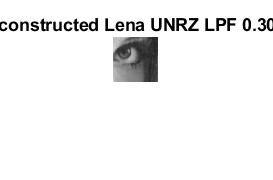



bitsM1 = reshape(bits_RX_UNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena UNRZ LPF 0.3045");

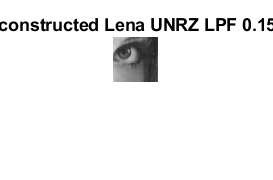


bitsM2 = reshape(bits_RX_UNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena UNRZ LPF 0.1545");

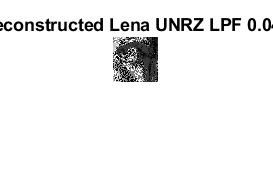


bitsM3 = reshape(bits_RX_UNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena UNRZ LPF 0.045");

## PNRZ


%xPNRZ_f_m1 = xPNRZ_filtrado_f1(start:mp:end);
%xPNRZ_f_m2 = xPNRZ_filtrado_f1(start:mp:end);
%xPNRZ_f_m3 = xPNRZ_filtrado_f1(start:mp:end);

bits_RX_PNRZ_1 = zeros(1,numel(bits2send));
bits_RX_PNRZ_2 = zeros(1,numel(bits2send));
bits_RX_PNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
xPNRZ_f_m1 = xPNRZ_filtrado_f1(start:mp:end);
xPNRZ_f_m2 = xPNRZ_filtrado_f2(start:mp:end);
xPNRZ_f_m3 = xPNRZ_filtrado_f3(start:mp:end);

bits_RX_PNRZ_1(xPNRZ_f_m1 > (max(xPNRZ_filtrado_f1)/2)) = 1;   %Umbral +
bits_RX_PNRZ_2(xPNRZ_f_m2 > (max(xPNRZ_filtrado_f2)/2)) = 1;   %Umbral +
bits_RX_PNRZ_3(xPNRZ_f_m3 > (max(xPNRZ_filtrado_f3)/2)) = 1;   %Umbral +

xPNRZ_BER_1 = (sum(xor(bits2send,bits_RX_PNRZ_1))/numel(bits2send)) * 100

xPNRZ_BER_1 = 0

xPNRZ_BER_2 = (sum(xor(bits2send,bits_RX_PNRZ_2))/numel(bits2send)) * 100

xPNRZ_BER_2 = 0

xPNRZ_BER_3 = (sum(xor(bits2send,bits_RX_PNRZ_3))/numel(bits2send)) * 100

xPNRZ_BER_3 = 38.4012

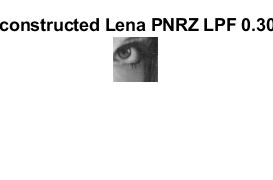


bitsM1 = reshape(bits_RX_PNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena PNRZ LPF 0.3045");

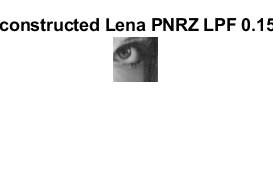


bitsM2 = reshape(bits_RX_PNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena PNRZ LPF 0.1545");

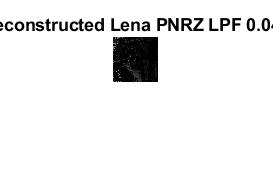


bitsM3 = reshape(bits_RX_PNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena PNRZ LPF 0.045");

## Manchester


%xMAN_f_m1 = xMANCH_filtrado_f1(start:mp:end);
%xMAN_f_m2 = xMANCH_filtrado_f1(start:mp:end);
%xMAN_f_m3 = xMANCH_filtrado_f1(start:mp:end);

%bits_RX_MAN_1 = zeros(1,numel(bits2send));
%bits_RX_MAN_2 = zeros(1,numel(bits2send));
%bits_RX_MAN_3 = zeros(1,numel(bits2send));

bits2send = bits';

%start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
start = ford/2 + round(mp/4);
start2 = ford/2 + round(3*mp/4);

x1MAN_f_m1 = xMANCH_filtrado_f1(start:mp:end);
x1MAN_f_m2 = xMANCH_filtrado_f2(start:mp:end);
x1MAN_f_m3 = xMANCH_filtrado_f3(start:mp:end);

x2MAN_f_m1 = xMANCH_filtrado_f1(start2:mp:end);
x2MAN_f_m2 = xMANCH_filtrado_f2(start2:mp:end);
x2MAN_f_m3 = xMANCH_filtrado_f3(start2:mp:end);

xMAN_f_m1 = sign(x1MAN_f_m1 - x2MAN_f_m1); %Sign
xMAN_f_m2 = sign(x1MAN_f_m2 - x2MAN_f_m2); %Sign
xMAN_f_m3 = sign(x1MAN_f_m3 - x2MAN_f_m3); %Sign


bits_RX_MAN_1 = (xMAN_f_m1+1)/2;
bits_RX_MAN_2 = (xMAN_f_m2+1)/2;
bits_RX_MAN_3 = (xMAN_f_m3+1)/2;

bits_RX_MAN_1 = bits_RX_MAN_1(1:numel(bits2send));
bits_RX_MAN_2 = bits_RX_MAN_2(1:numel(bits2send));
bits_RX_MAN_3 = bits_RX_MAN_3(1:numel(bits2send));


xMAN_BER_1 = (sum(xor(bits2send,bits_RX_MAN_1))/numel(bits2send)) * 100

xMAN_BER_1 = 0

xMAN_BER_2 = (sum(xor(bits2send,bits_RX_MAN_2))/numel(bits2send)) * 100

xMAN_BER_2 = 6.7469

xMAN_BER_3 = (sum(xor(bits2send,bits_RX_MAN_3))/numel(bits2send)) * 100

xMAN_BER_3 = 14.7963


bitsM1 = reshape(bits_RX_MAN_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena PNRZ LPF 0.3045");

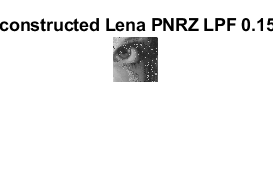


bitsM2 = reshape(bits_RX_MAN_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena PNRZ LPF 0.1545");

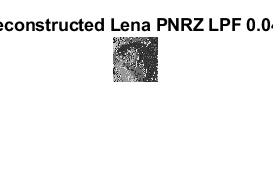


bitsM3 = reshape(bits_RX_MAN_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena PNRZ LPF 0.045");

## AMI


%xAMI_f_m1 = xAMI_filtrado_f1(start:mp:end);
%xAMI_f_m2 = xAMI_filtrado_f1(start:mp:end);
%xAMI_f_m3 = xAMI_filtrado_f1(start:mp:end);

bits_RX_AMI_1 = zeros(1,numel(bits2send));
bits_RX_AMI_2 = zeros(1,numel(bits2send));
bits_RX_AMI_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
xAMI_f_m1 = xAMI_filtrado_f1(start:mp:end);
xAMI_f_m2 = xAMI_filtrado_f2(start:mp:end);
xAMI_f_m3 = xAMI_filtrado_f3(start:mp:end);

bits_RX_AMI_1(xAMI_f_m1 > (max(xAMI_filtrado_f1)/2)) = 1;   %Umbral +
bits_RX_AMI_2(xAMI_f_m2 > (max(xAMI_filtrado_f2)/2)) = 1;   %Umbral +
bits_RX_AMI_3(xAMI_f_m3 > (max(xAMI_filtrado_f3)/2)) = 1;   %Umbral +

xAMI_BER_1 = (sum(xor(bits2send,bits_RX_AMI_1))/numel(bits2send)) * 100

xAMI_BER_1 = 24.2593

xAMI_BER_2 = (sum(xor(bits2send,bits_RX_AMI_2))/numel(bits2send)) * 100

xAMI_BER_2 = 24.2593

xAMI_BER_3 = (sum(xor(bits2send,bits_RX_AMI_3))/numel(bits2send)) * 100

xAMI_BER_3 = 48.1728

## EJERCICIO 2

L = 100;
Triangular_pulse = triang(L); %Pulso triangular de 100 muestras
Ep = sum(Triangular_pulse.*Triangular_pulse) %Energía del pulso

Ep = 33.3300

E1 = max(conv(Triangular_pulse,fliplr(Triangular_pulse))) %Máximo de la convolución

E1 = 33.3300

E2 = conv(Triangular_pulse,fliplr(Triangular_pulse));
E2(L) %Elemento 100 de la convolución

ans = 33.3300

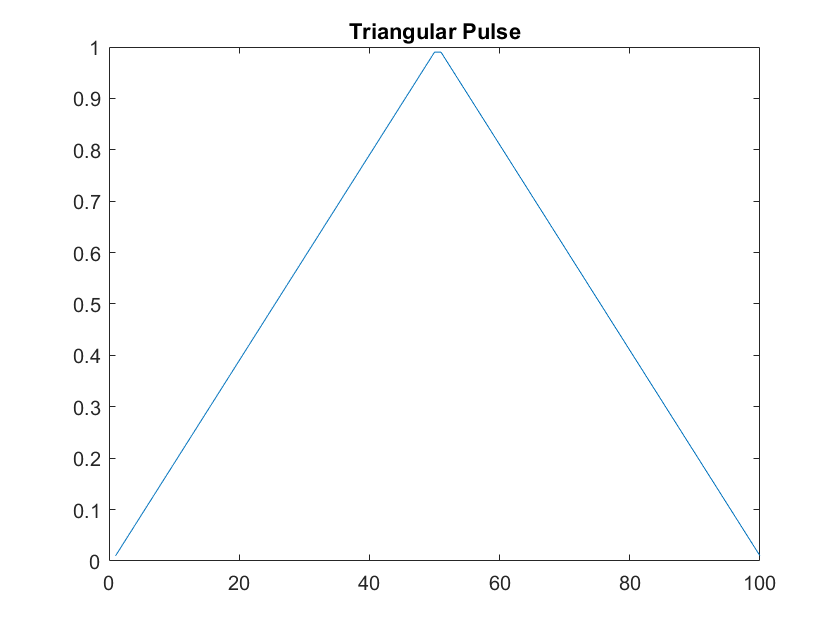

figure();
plot(Triangular_pulse);
title("Triangular Pulse");

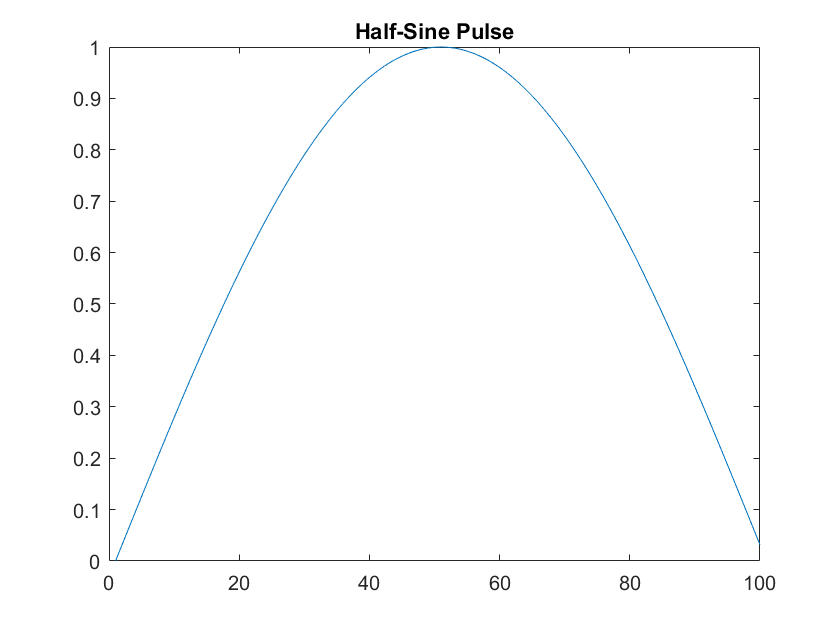

t_hs = 0:1/100:1-1/100;
f_hs = 0.5;
Half_sine_pulse = sin(2*pi*f_hs*t_hs);
Half_sine_pulse = Half_sine_pulse';
figure();
plot(Half_sine_pulse);
title("Half-Sine Pulse");

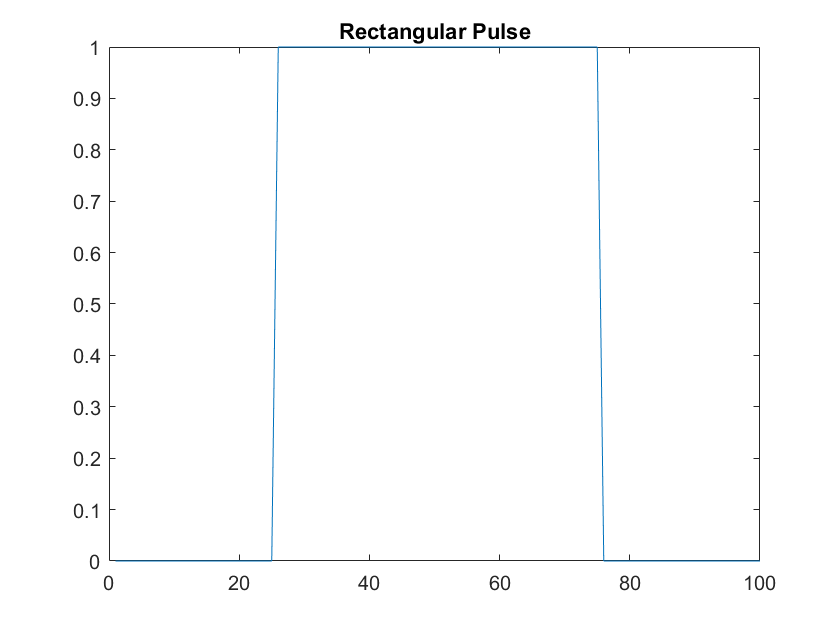

Rectangular_pulse = [zeros(1,100/4) ones(1,100/2) zeros(1,100/4)];
Rectangular_pulse = Rectangular_pulse';

figure();
plot(Rectangular_pulse);
title("Rectangular Pulse");

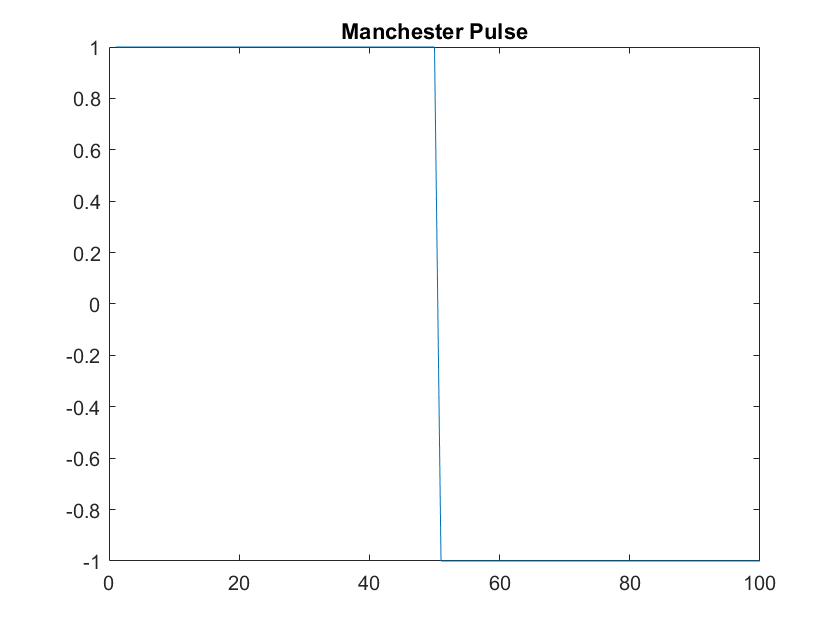

Manchester_pulse = [ones(1,100/2) -ones(1,100/2)];
Manchester_pulse = Manchester_pulse';
figure();
plot(Manchester_pulse);
title("Manchester Pulse");

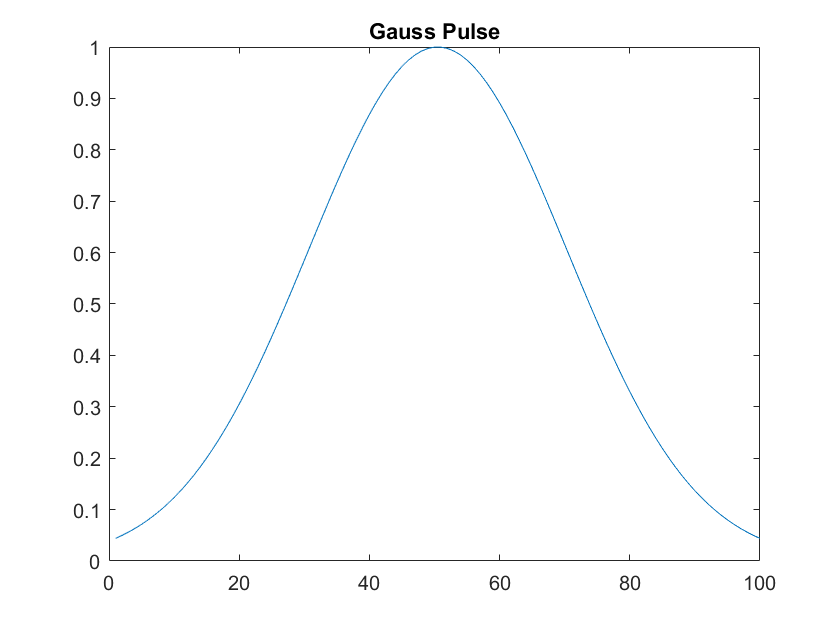

Gauss_pulse = gausswin(L);
figure();
plot(Gauss_pulse);
title("Gauss Pulse");

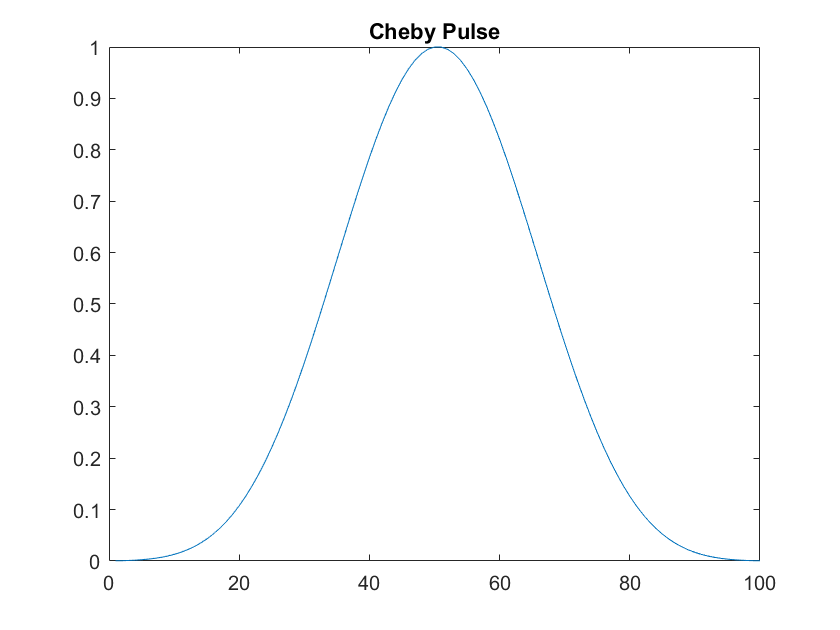

Cheby_pulse = chebwin(L);
figure();
plot(Cheby_pulse);
title("Cheby Pulse");

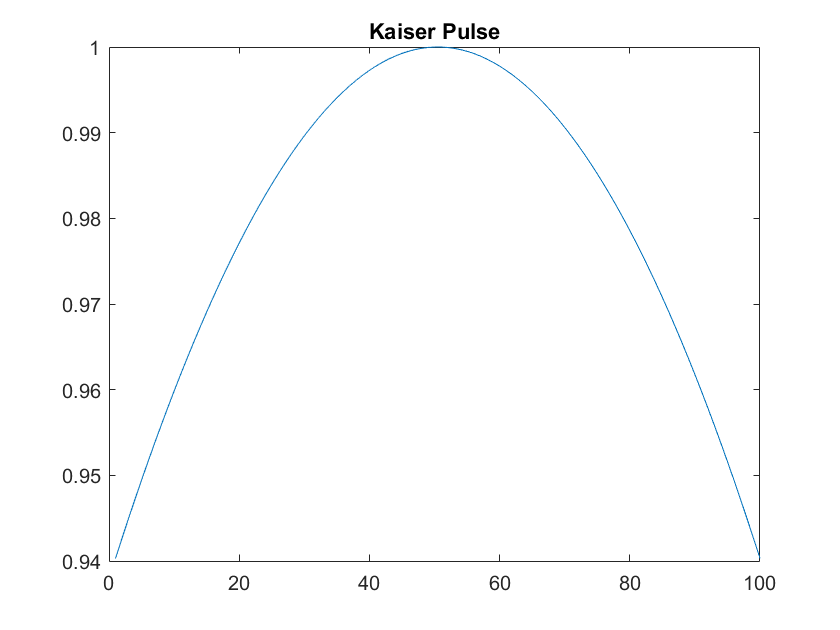

Kaiser_pulse = kaiser(L);
figure();
plot(Kaiser_pulse);
title("Kaiser Pulse");

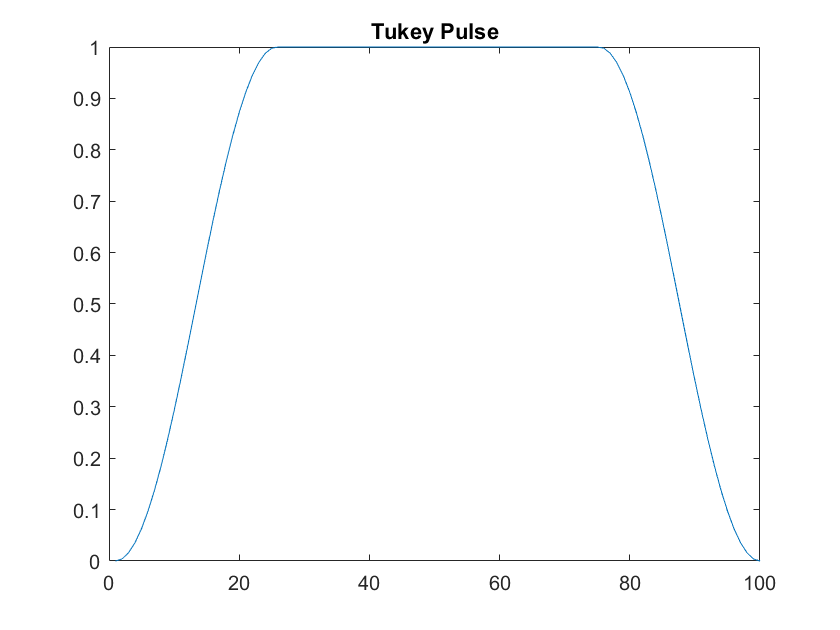

Tukey_pulse = tukeywin(L);
figure();
plot(Tukey_pulse);
title("Tukey Pulse");

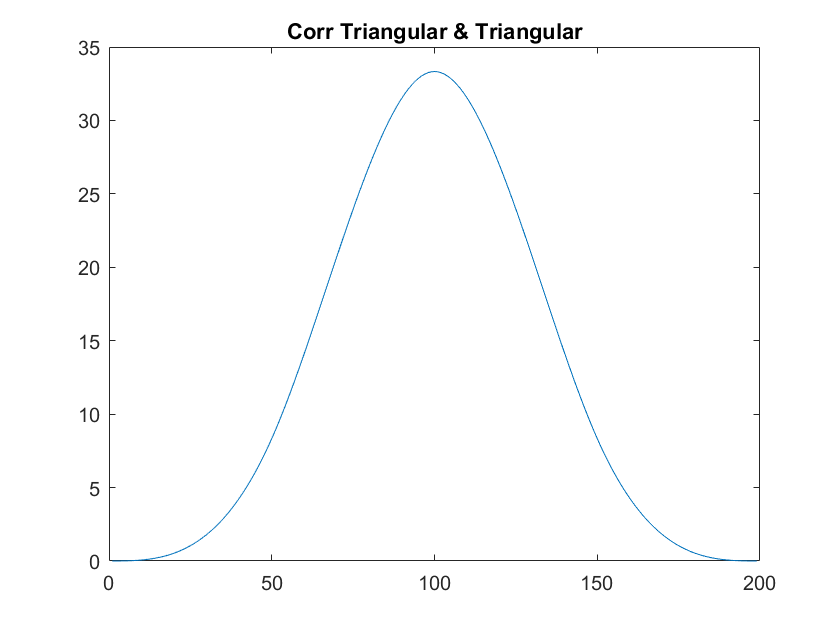




% Haciendo la correlación con el pulso triangular
Triangular_corr = xcorr(Triangular_pulse, Triangular_pulse);
figure;
plot(Triangular_corr);
title("Corr Triangular & Triangular");

max_Triangular_corr = max(Triangular_corr)

max_Triangular_corr = 33.3300

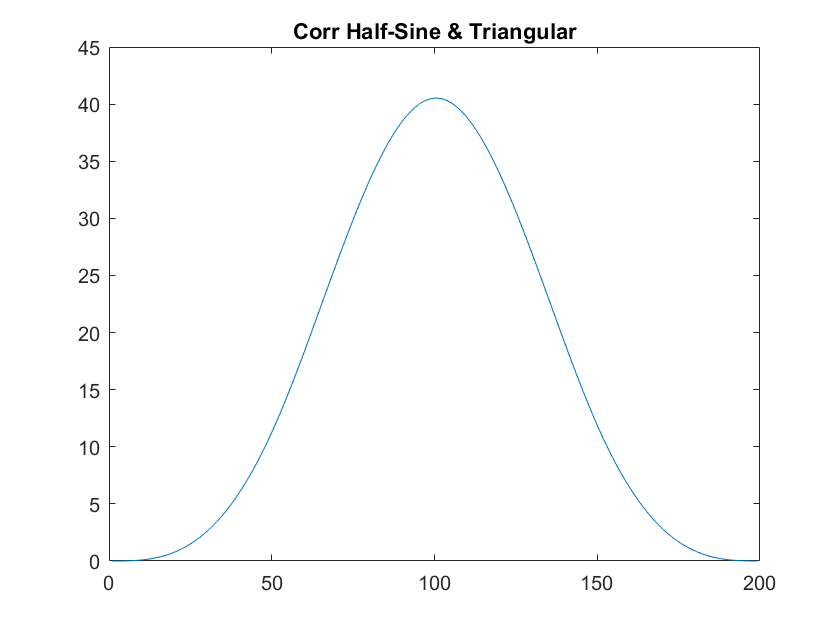

HalfSine_corr = xcorr(Half_sine_pulse, Triangular_pulse);
figure;
plot(HalfSine_corr);
title("Corr Half-Sine & Triangular");

max_HalfSine_corr = max(HalfSine_corr)

max_HalfSine_corr = 40.5218

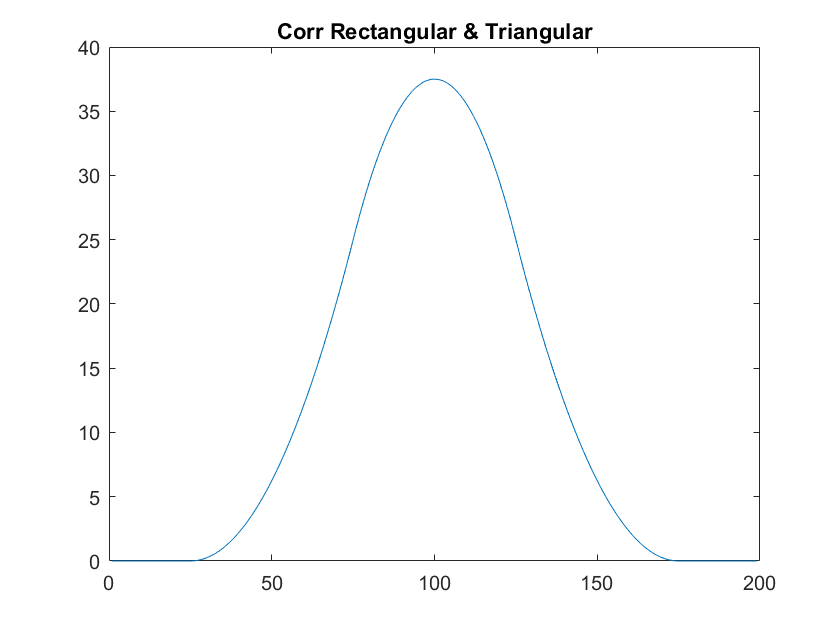

Rectangular_corr = xcorr(Rectangular_pulse, Triangular_pulse);
figure;
plot(Rectangular_corr);
title("Corr Rectangular & Triangular");

max_Rectangular_corr = max(Rectangular_corr)

max_Rectangular_corr = 37.5000

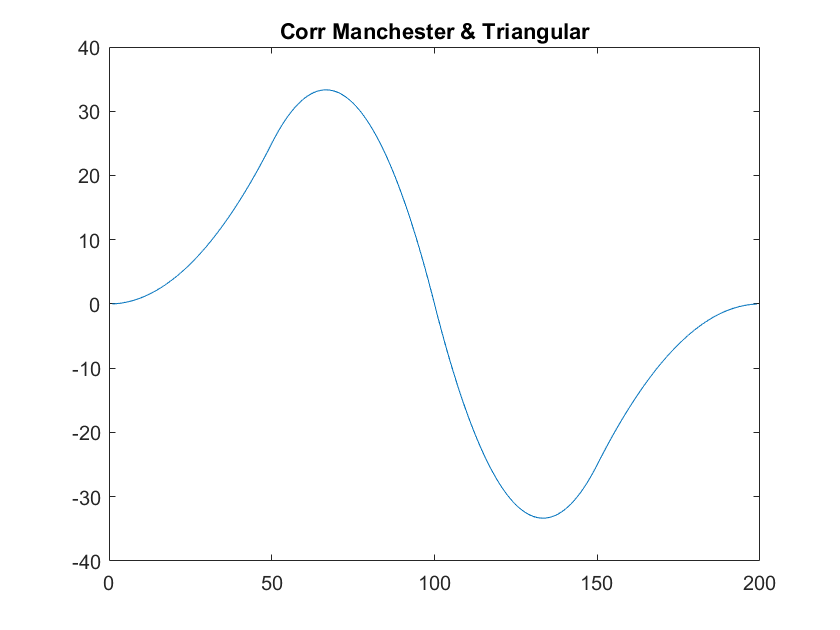

Manchester_corr = xcorr(Manchester_pulse, Triangular_pulse);
figure;
plot(Manchester_corr);
title("Corr Manchester & Triangular");

max_Manchester_corr = max(Manchester_corr)

max_Manchester_corr = 33.3300

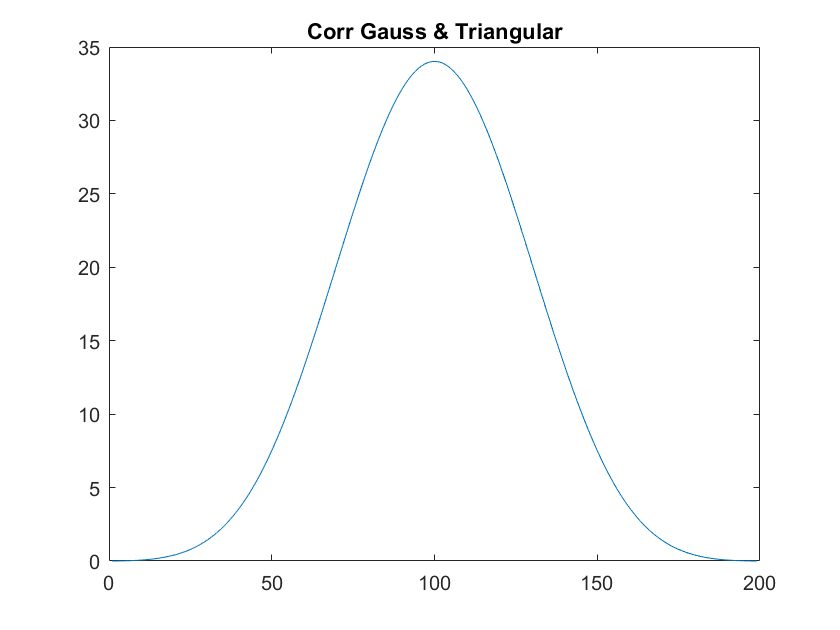

Gauss_corr = xcorr(Gauss_pulse, Triangular_pulse);
figure;
plot(Gauss_corr);
title("Corr Gauss & Triangular");

max_Gauss_corr = max(Gauss_corr)

max_Gauss_corr = 34.0209

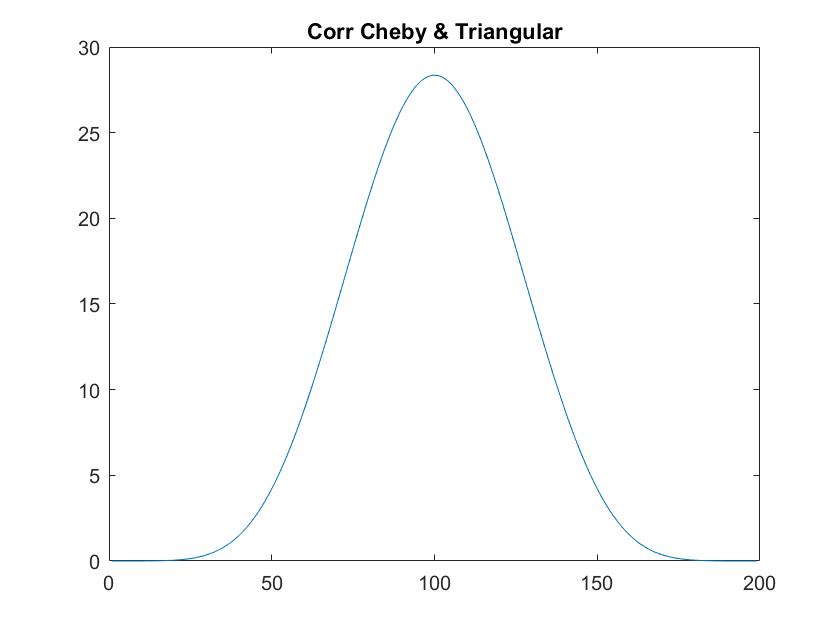

Cheby_corr = xcorr(Cheby_pulse, Triangular_pulse);
figure;
plot(Cheby_corr);
title("Corr Cheby & Triangular");

max_Cheby_corr = max(Cheby_corr)

max_Cheby_corr = 28.3560

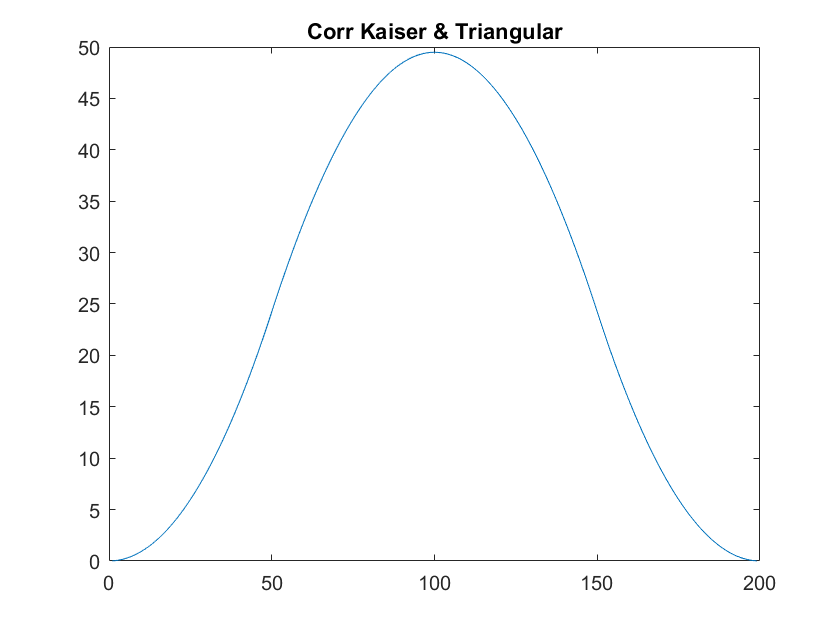

Kaiser_corr = xcorr(Kaiser_pulse, Triangular_pulse);
figure;
plot(Kaiser_corr);
title("Corr Kaiser & Triangular");

max_Kaiser_corr = max(Kaiser_corr)

max_Kaiser_corr = 49.4877

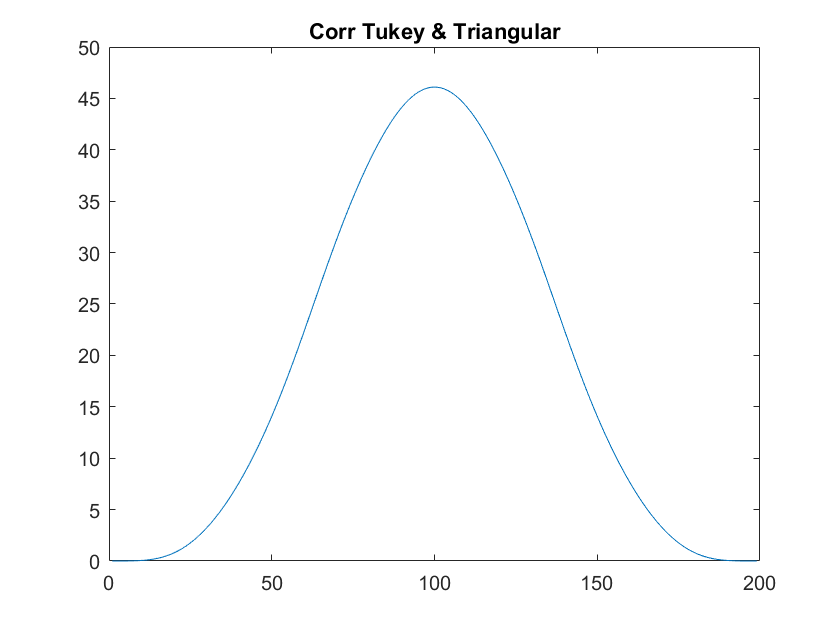

Tukey_corr = xcorr(Tukey_pulse, Triangular_pulse);
figure;
plot(Tukey_corr);
title("Corr Tukey & Triangular");

max_Tukey_corr = max(Tukey_corr)

max_Tukey_corr = 46.1028

## EJERCICIO 3

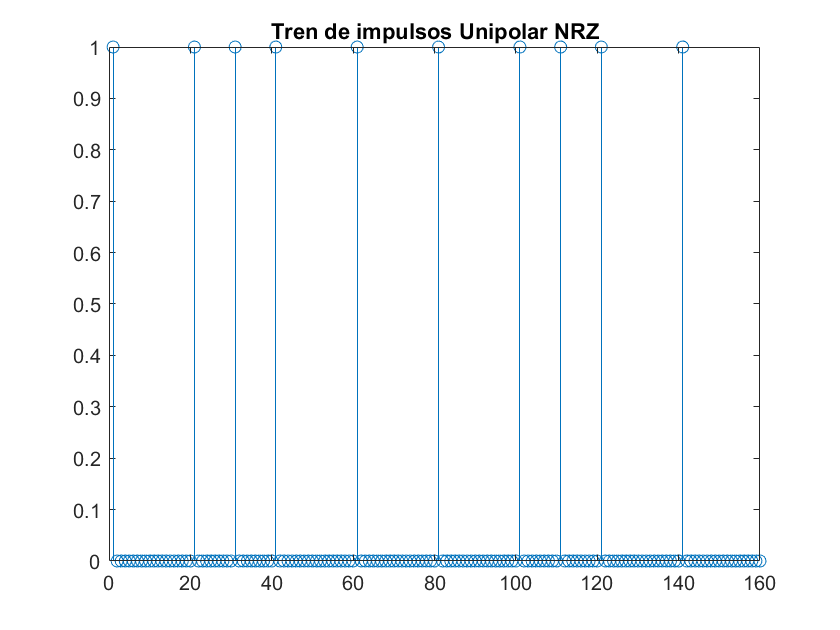


%pnrz = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; % Pulse type with mp samples
pnrz =ones(1,mp); % Similar to Arduino pulses with 5V----PBase
%wvtool(pnrz)

s = zeros(1,numel(bits)*mp);
s(1:mp:end) = bits;  % Impulse Train
stem(s(1:mp*16))
title('Tren de impulsos Unipolar NRZ');

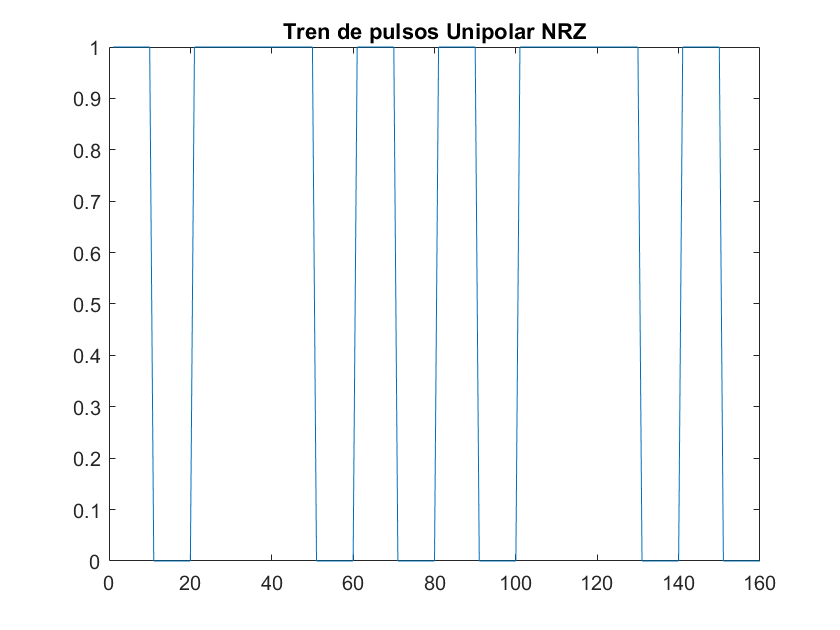

xUNRZ = conv(pnrz,s); % Pulse Train
plot(xUNRZ(1:mp*16))
title('Tren de pulsos Unipolar NRZ');

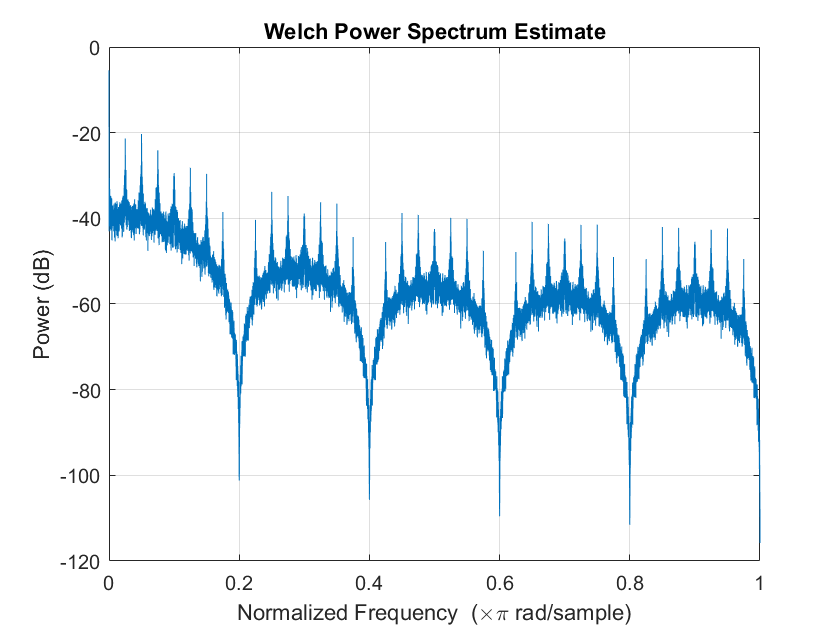

pwelch(xUNRZ,[],[],[],'power'); % PSD of Unipolar NRZ

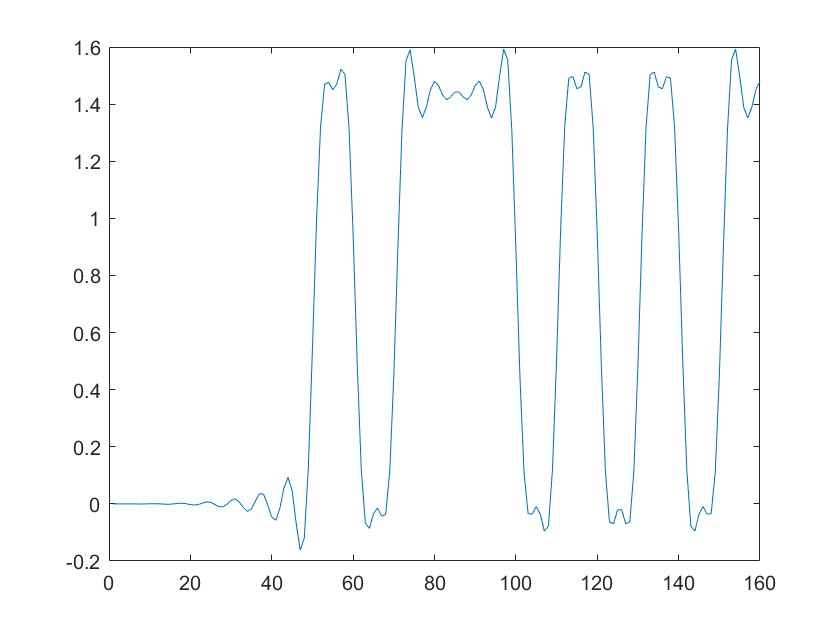

%%wvtool(xUNRZ)

pow = sum(xUNRZ.^2)/numel(xUNRZ);
pow_Deseada = 1;
xUNRZ = sqrt(pow_Deseada/pow)*xUNRZ;

xUNRZ_filtrado_f1 = conv(xUNRZ,f1);
xUNRZ_filtrado_f2 = conv(xUNRZ,f2);
xUNRZ_filtrado_f3 = conv(xUNRZ,f3);

%c)
plot(xUNRZ_filtrado_f1(1:mp*16));

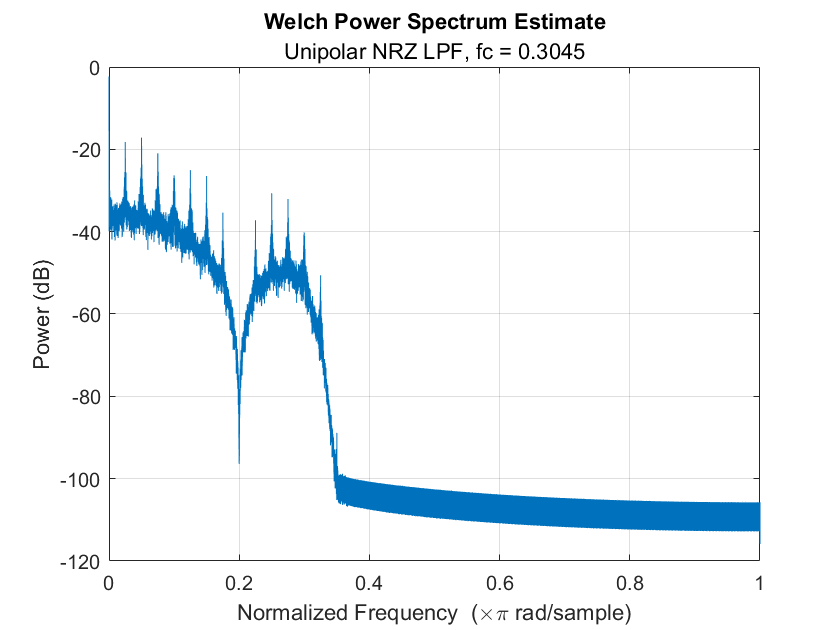

pwelch(xUNRZ_filtrado_f1,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.3045"); 

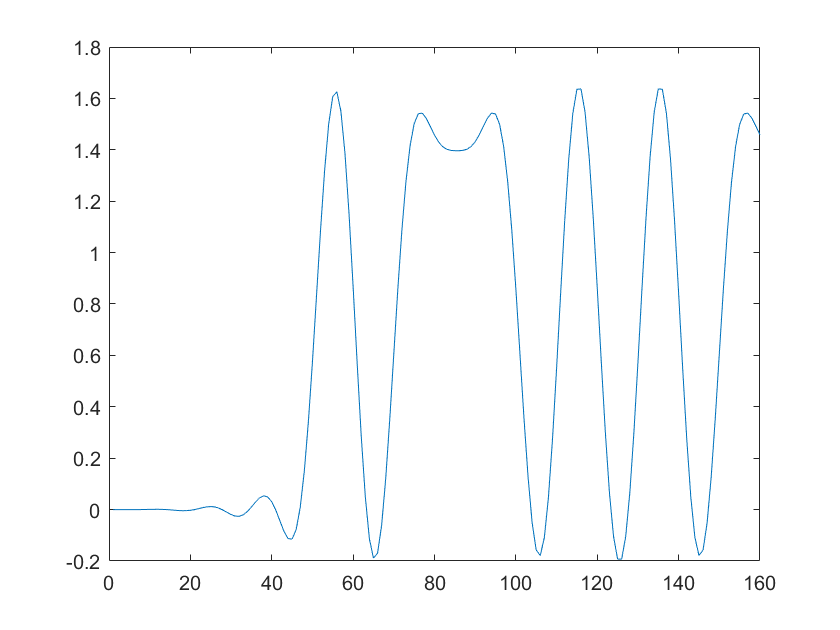

plot(xUNRZ_filtrado_f2(1:mp*16));

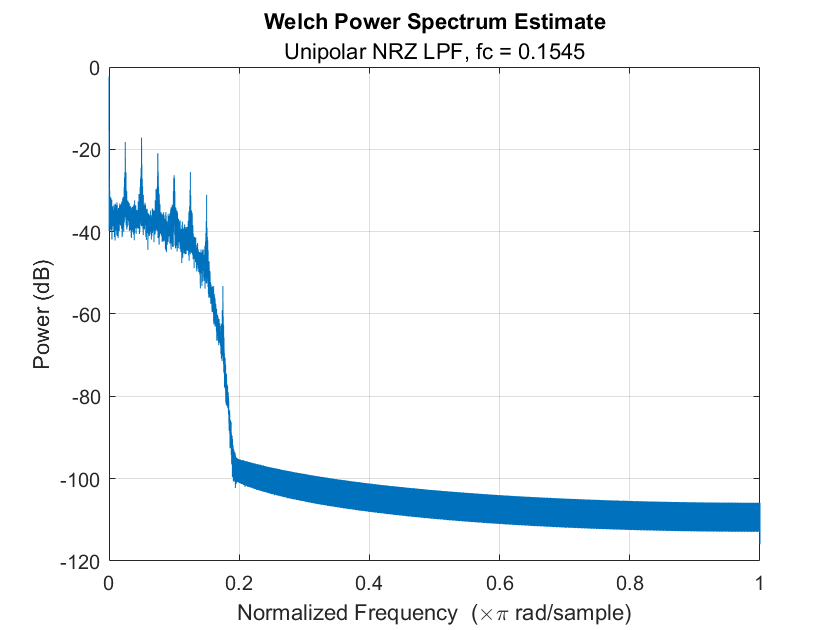

pwelch(xUNRZ_filtrado_f2,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.1545"); 

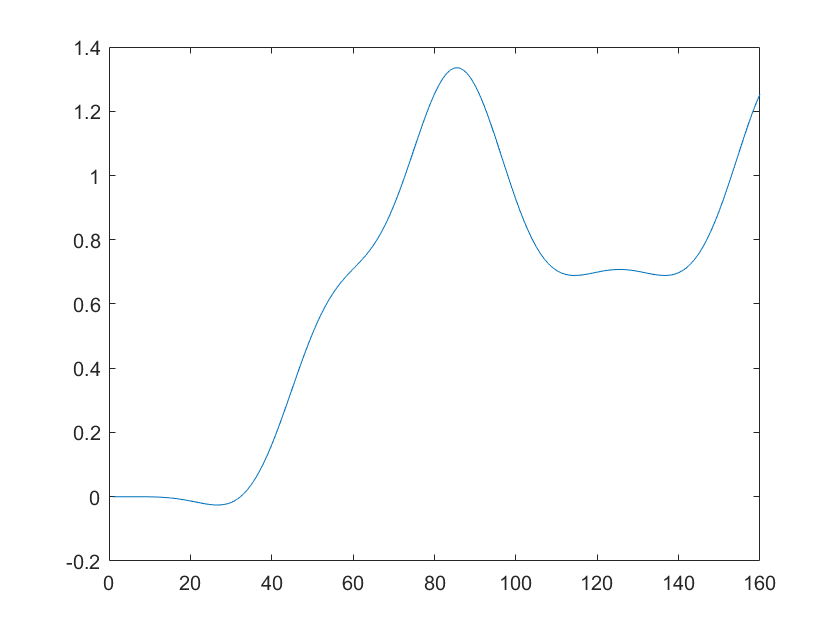

plot(xUNRZ_filtrado_f3(1:mp*16));

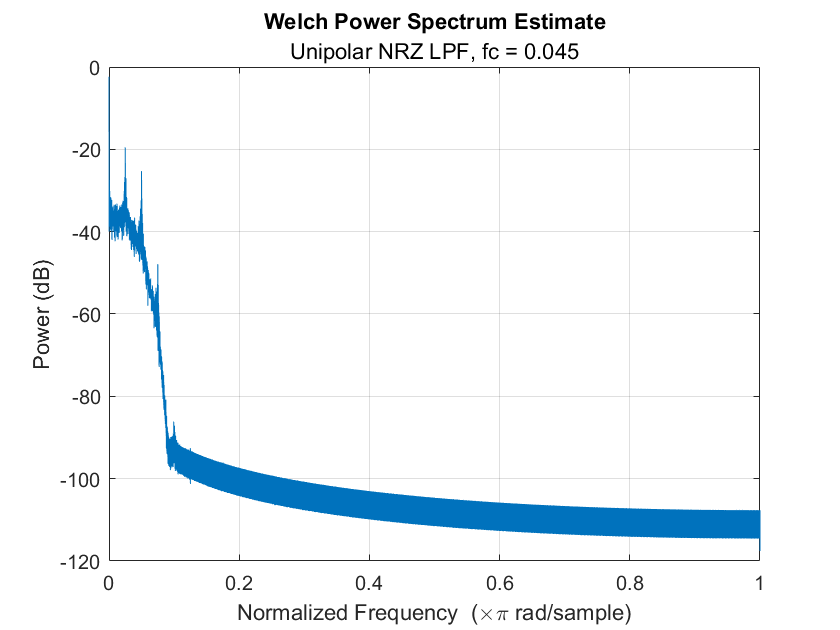

pwelch(xUNRZ_filtrado_f3,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.045"); 

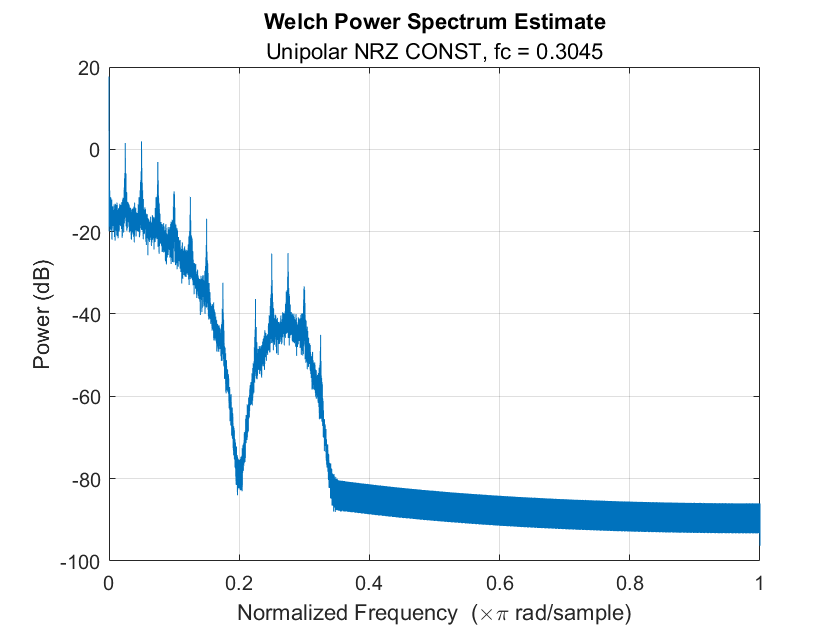


Match_filter1 = fliplr(pnrz);

Const1 =conv(Match_filter1,xUNRZ_filtrado_f1);
Const2 =conv(Match_filter1,xUNRZ_filtrado_f2);
Const3 =conv(Match_filter1,xUNRZ_filtrado_f3);

pwelch(Const1,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

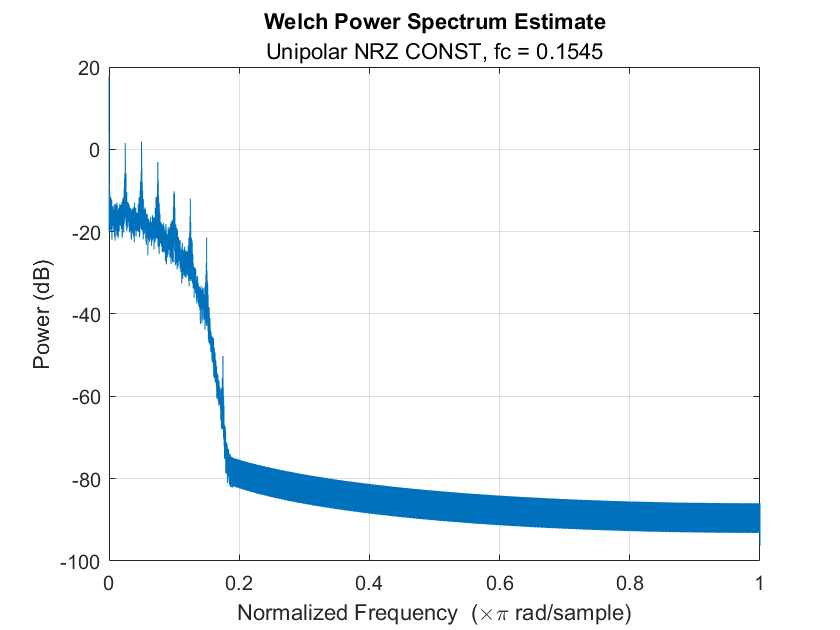

pwelch(Const2,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

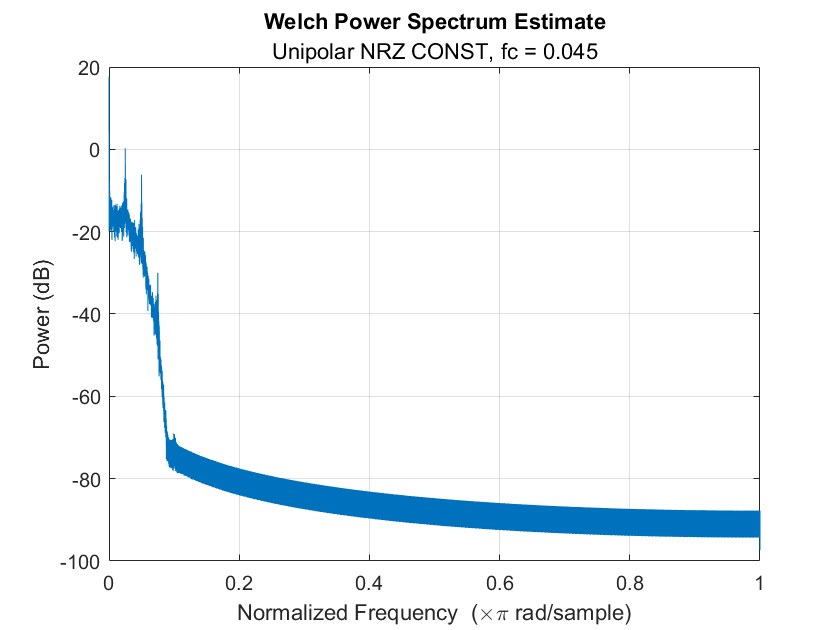

pwelch(Const3,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 



% 1.e) recover the transmitted bits
% UNRZ
bits2send = bits';
bits_RX_UNRZ_1 = zeros(1,numel(bits2send));
bits_RX_UNRZ_2 = zeros(1,numel(bits2send));
bits_RX_UNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2) + (mp/2) ; % Take to account the delay produced by the filter
xUNRZ_f_m1 = Const1(start:mp:end);
xUNRZ_f_m2 = Const2(start:mp:end);
xUNRZ_f_m3 = Const3(start:mp:end);

bits_RX_UNRZ_1(xUNRZ_f_m1 > (max(Const1)/2)) = 1;   %Umbral +
bits_RX_UNRZ_2(xUNRZ_f_m2 > (max(Const2)/2)) = 1;   %Umbral +
bits_RX_UNRZ_3(xUNRZ_f_m3 > (max(Const3)/2)) = 1;   %Umbral +

xUNRZ_BER_1 = (sum(xor(bits2send,bits_RX_UNRZ_1))/numel(bits2send)) * 100

xUNRZ_BER_1 = 0

xUNRZ_BER_2 = (sum(xor(bits2send,bits_RX_UNRZ_2))/numel(bits2send)) * 100

xUNRZ_BER_2 = 0

xUNRZ_BER_3 = (sum(xor(bits2send,bits_RX_UNRZ_3))/numel(bits2send)) * 100

xUNRZ_BER_3 = 23.2593



bitsM1 = reshape(bits_RX_UNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena UNRZ LPF 0.3045");


bitsM2 = reshape(bits_RX_UNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena UNRZ LPF 0.1545");


bitsM3 = reshape(bits_RX_UNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena UNRZ LPF 0.045");

## PNRZ

pnrz=ones(1,mp);
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))
title('Tren de impulsos Polar NRZ');

xPNRZ=conv(pnrz,s); %Pulse train
plot(xPNRZ(1:mp*16))
title('Tren de pulsos Polar NRZ');

pwelch(xPNRZ,500,300,500,Fs,'power');


pow = sum(xPNRZ.^2)/numel(xPNRZ);
pow_Deseada = 1;
xPNRZ = sqrt(pow_Deseada/pow)*xPNRZ;

xPNRZ_filtrado_f1 = conv(xPNRZ,f1);
xPNRZ_filtrado_f2 = conv(xPNRZ,f2);
xPNRZ_filtrado_f3 = conv(xPNRZ,f3);

%c)
plot(xPNRZ_filtrado_f1(1:mp*16));

pwelch(xPNRZ_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.3045"); 

plot(xPNRZ_filtrado_f2(1:mp*16));

pwelch(xPNRZ_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.1545"); 

plot(xPNRZ_filtrado_f3(1:mp*16));

pwelch(xPNRZ_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.045"); 

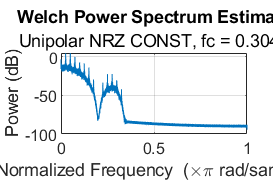

%match filter
Match_filter2 = fliplr(pnrz);

Const11 =conv(Match_filter2,xPNRZ_filtrado_f1);
Const22 =conv(Match_filter2,xPNRZ_filtrado_f2);
Const33 =conv(Match_filter2,xPNRZ_filtrado_f3);

pwelch(Const11,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

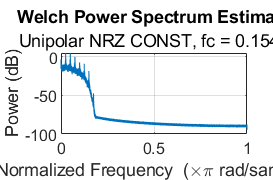

pwelch(Const22,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

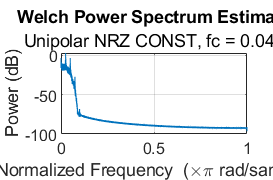

pwelch(Const33,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 


bits_RX_PNRZ_1 = zeros(1,numel(bits2send));
bits_RX_PNRZ_2 = zeros(1,numel(bits2send));
bits_RX_PNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2) + (mp/2); % Take to account the delay produced by the filter
xPNRZ_f_m1 = Const11(start:mp:end);
xPNRZ_f_m2 = Const22(start:mp:end);
xPNRZ_f_m3 = Const33(start:mp:end);

bits_RX_PNRZ_1(xPNRZ_f_m1 > (max(Const11)/2)) = 1;   %Umbral +
bits_RX_PNRZ_2(xPNRZ_f_m2 > (max(Const22)/2)) = 1;   %Umbral +
bits_RX_PNRZ_3(xPNRZ_f_m3 > (max(Const33)/2)) = 1;   %Umbral +

xPNRZ_BER_1 = (sum(xor(bits2send,bits_RX_PNRZ_1))/numel(bits2send)) * 100

xPNRZ_BER_1 = 0

xPNRZ_BER_2 = (sum(xor(bits2send,bits_RX_PNRZ_2))/numel(bits2send)) * 100

xPNRZ_BER_2 = 0

xPNRZ_BER_3 = (sum(xor(bits2send,bits_RX_PNRZ_3))/numel(bits2send)) * 100

xPNRZ_BER_3 = 38.3765


bitsM1 = reshape(bits_RX_PNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena PNRZ LPF 0.3045");


bitsM2 = reshape(bits_RX_PNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena PNRZ LPF 0.1545");

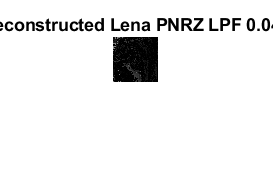


bitsM3 = reshape(bits_RX_PNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena PNRZ LPF 0.045");

## MANCHESTER

pm=[ones(1,mp/2),-1*ones(1,mp/2)]; 
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(bits)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Manchester');

xMANCH=conv(pm,s);
plot(xMANCH(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Manchester');

pwelch(xMANCH,500,300,500,Fs,'power');


pow = sum(xMANCH.^2)/numel(xMANCH);
pow_Deseada = 1;
xMANCH = sqrt(pow_Deseada/pow)*xMANCH;

xMANCH_filtrado_f1 = conv(xMANCH,f1);
xMANCH_filtrado_f2 = conv(xMANCH,f2);
xMANCH_filtrado_f3 = conv(xMANCH,f3);

%c)
plot(xMANCH_filtrado_f1(1:mp*16));

pwelch(xMANCH_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.3045"); 

plot(xMANCH_filtrado_f2(1:mp*16));

pwelch(xMANCH_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.1545"); 

plot(xMANCH_filtrado_f3(1:mp*16));

pwelch(xMANCH_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.045"); 

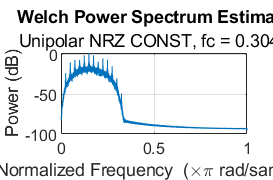



%match filter
Match_filter3 = fliplr(pm);

Const111 =conv(Match_filter3,xMANCH_filtrado_f1);
Const222 =conv(Match_filter3,xMANCH_filtrado_f2);
Const333 =conv(Match_filter3,xMANCH_filtrado_f3);

pwelch(Const111,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

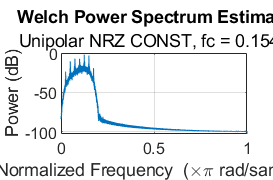

pwelch(Const222,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

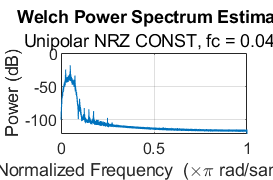

pwelch(Const333,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 


%start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
start = ford/2 + round(mp/4);
start2 = ford/2 + round(mp/2);

x1MAN_f_m1 = Const111(start:mp:end);
x1MAN_f_m2 = Const222(start:mp:end);
x1MAN_f_m3 = Const333(start:mp:end);

x2MAN_f_m1 = Const111(start2:mp:end);
x2MAN_f_m2 = Const222(start2:mp:end);
x2MAN_f_m3 = Const333(start2:mp:end);

xMAN_f_m1 = sign(x2MAN_f_m1 - x1MAN_f_m1); %Sign
xMAN_f_m2 = sign(x2MAN_f_m2 - x1MAN_f_m2); %Sign
xMAN_f_m3 = sign(x2MAN_f_m3 - x1MAN_f_m3); %Sign


bits_RX_MAN_1 = (xMAN_f_m1+1)/2;
bits_RX_MAN_2 = (xMAN_f_m2+1)/2;
bits_RX_MAN_3 = (xMAN_f_m3+1)/2;

bits_RX_MAN_1 = bits_RX_MAN_1(1:numel(bits2send));
bits_RX_MAN_2 = bits_RX_MAN_2(1:numel(bits2send));
bits_RX_MAN_3 = bits_RX_MAN_3(1:numel(bits2send));


xMAN_BER_1 = (sum(xor(bits2send,bits_RX_MAN_1))/numel(bits2send)) * 100

xMAN_BER_1 = 47.3519

xMAN_BER_2 = (sum(xor(bits2send,bits_RX_MAN_2))/numel(bits2send)) * 100

xMAN_BER_2 = 37.4074

xMAN_BER_3 = (sum(xor(bits2send,bits_RX_MAN_3))/numel(bits2send)) * 100

xMAN_BER_3 = 22.9136

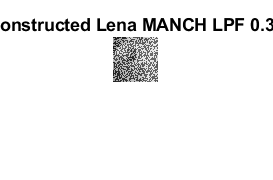


bitsM1 = reshape(bits_RX_MAN_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena MANCH LPF 0.3045");

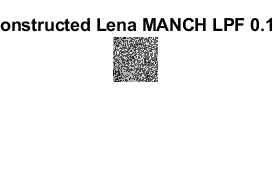


bitsM2 = reshape(bits_RX_MAN_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena MANCH LPF 0.1545");

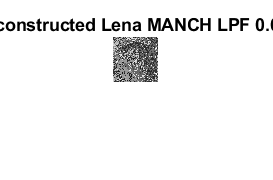


bitsM3 = reshape(bits_RX_MAN_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena MANCH LPF 0.045");